% Load point cloud data from Lidar and stereo camera
lidar_pts = loadLidarPointCloud();
camera_pts = loadStereoCameraPointCloud();

% or Generate synthetic point cloud data
% [lidar_pts, camera_pts] = generatePointCloudData();

Firstly I plot the preprocessed an denoised point clouds on the same figure. After that, I apply the proposed sensor fusion method.

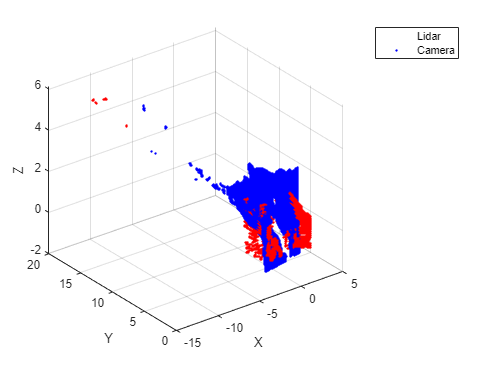

% Create figure
figure;

% Visualize Lidar point cloud
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3), 'r', 'Marker', '.');
hold on;

% Visualize camera point cloud
scatter3(camera_pts(:,1), camera_pts(:,2), camera_pts(:,3), 'b', 'Marker', '.');
hold off;

% Add legend and labels
legend('Lidar', 'Camera');
xlabel('X');
ylabel('Y');
zlabel('Z');

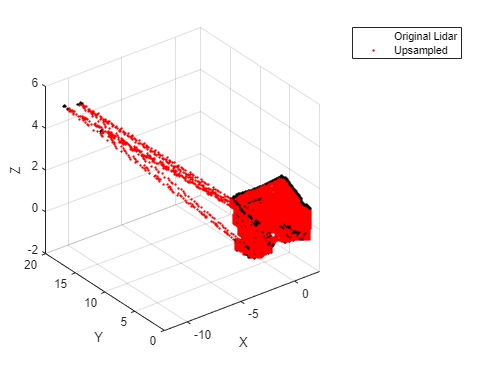

% Upsample Lidar point cloud with Interpolation
lidar_pts_upsampled = upsampleLidar(lidar_pts, camera_pts);

% Create figure
figure;

% Visualize original Lidar point cloud
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3), 'k', 'Marker', '.');
hold on;

% Visualize filtered point cloud
scatter3(lidar_pts_upsampled(:,1), lidar_pts_upsampled(:,2), lidar_pts_upsampled(:,3), 'r', 'Marker', '.');
hold off;

% Add legend and labels
legend('Original Lidar', 'Upsampled');
xlabel('X');
ylabel('Y');
zlabel('Z');

The Papoulis-Gerchberg algorithm is a method for reconstructing an image from its Fourier transform magnitude and a known phase constraint. It can be used to improve the resolution of a lidar point cloud by iteratively updating the phase of the Fourier transform of the point cloud while enforcing a constraint on the known magnitude of the point cloud.

% Upsample Lidar point cloud with Papoulis-Gerchberg algorithm
% N = length(camera_pts);
% M = length(lidar_pts);
% L = 10;
% 
% lidar_pts_pg = papoulis_gerchberg(lidar_pts, 3);

pc_fft = fftn(lidar_pts)

pc_fft = 17581×3 single matrix
	1.0e+04 *

   5.8029 + 0.0000i  -3.1440 - 4.8386i  -3.1440 + 4.8386i
   0.9017 - 1.4876i  -0.1324 - 2.9337i  -0.9740 - 1.3928i
  -0.4728 + 0.8632i   0.7127 + 1.0104i   0.2142 + 0.0550i
  -0.1951 - 0.0253i   0.1061 - 0.3479i  -0.3481 - 0.4135i
   0.2322 + 0.8145i   0.3555 - 0.0394i  -0.4399 + 0.2703i
   0.2903 + 0.0227i   0.1645 - 0.6399i  -0.3481 - 0.1173i
   0.3664 + 0.2118i   0.0206 - 0.0178i  -0.0512 + 0.3833i
   0.0638 - 0.2979i  -0.1509 - 0.3027i  -0.0875 - 0.1641i
   0.0187 + 0.0400i   0.0496 + 0.2795i   0.1891 + 0.1327i
  -0.0624 - 0.1996i  -0.1592 - 0.0846i  -0.0536 - 0.0215i


pc_fft_magn = abs(pc_fft)



% Preprocess Lidar point cloud using Poisson-Gerchberg algorithm to eliminate noise
lidar_pts_filtered = poissonGerchberg(lidar_pts);

% Create figure
figure;

% Visualize original Lidar point cloud
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3), 'k', 'Marker', '.');
hold on;

% Visualize filtered point cloud
scatter3(lidar_pts_filtered(:,1), lidar_pts_filtered(:,2), lidar_pts_filtered(:,3), 'r', 'Marker', '.');
hold off;

% Add legend and labels
legend('Original Lidar', 'Filtered');
xlabel('X');
ylabel('Y');
zlabel('Z');

% Set blending factor for Poisson-Gerchberg algorithm
alpha = 0.5;

% Set time step
dt = 0.1;

% Initialize variables
vel_prev = [0 0 0];
accel = [0 0 0];
pos_prev = [0 0 0];

long_term_pts = camera_pts;
short_term_pts = lidar_pts_upsampled;

% Loop through point clouds
for i = 2:size(lidar_pts, 1)
   % Compute acceleration between current and previous points
   accel = computeAcceleration(short_term_pts(i-1,:), short_term_pts(i,:), vel_prev, dt);
   
   % Update velocity and position using acceleration
   vel = vel_prev + accel * dt;
   pos = pos_prev + vel * dt;
   
   % Store current velocity and position for next iteration
   vel_prev = vel;
   pos_prev = pos;
   
   % Update filtered point cloud using blending factor
   long_term_pts = alpha * short_term_pts + (1 - alpha) * long_term_pts;
end

filtered_pts = long_term_pts;

% Visualize filtered point cloud
figure;
scatter3(filtered_pts(:,1), filtered_pts(:,2), filtered_pts(:,3), 'Marker', '.');
title('Filtered Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

## Function Definitions

function accel = computeAcceleration(pt1, pt2, vel_prev, dt)
    % computeAcceleration computes the linear acceleration between two points and a given time step
    % 
    % Inputs:
    %   pt1: 3D point at time t
    %   pt2: 3D point at time t+dt
    %   vel_prev: velocity at time t
    %   dt: time step
    % 
    % Output:
    %   accel: linear acceleration between pt1 and pt2
    
    % Compute velocity between pt1 and pt2
    vel = (pt2 - pt1) / dt;
    
    % Compute acceleration as change in velocity over time
    accel = (vel - vel_prev) / dt;
end

function ptCloudFiltered = poissonGerchberg(ptCloud)
    % poissonGerchberg applies the Poisson-Gerchberg algorithm to denoise a 3D Lidar point cloud
    % 
    % Inputs:
    %   ptCloud: Nx3 matrix of 3D Lidar point cloud data, where N is the number of points
    % 
    % Output:
    %   ptCloudFiltered: Nx3 matrix of denoised 3D Lidar point cloud data
    
    % Set maximum number of iterations and tolerance for convergence
    maxIter = 1000;
    tol = 1e-6;
    
    % Initialize filtered point cloud to input point cloud
    ptCloudFiltered = ptCloud;

    % Iteratively apply Poisson-Gerchberg algorithm to denoise point cloud
    for i = 1:maxIter
       % Compute distance transform of filtered point cloud
       distTransform = bwdist(~isnan(ptCloudFiltered));
       
       % Interpolate missing points in filtered point cloud using distance transform
       ptCloudInterp = ptCloud;
       ptCloudInterp(isnan(ptCloudFiltered)) = distTransform(isnan(ptCloudFiltered));
       
       % Compute difference between interpolated and filtered point clouds
       diff = ptCloudInterp - ptCloudFiltered;
       
       % Check for convergence
       if norm(diff) < tol
          break;
       end
       
       % Update filtered point cloud using interpolated point cloud
       ptCloudFiltered = alpha * ptCloudInterp + (1 - alpha) * ptCloudFiltered;
    end
end

function ptCloud = loadLidarPointCloud()
    % loadLidarPointCloud loads and returns a 3D Lidar point cloud
    
    % Load Lidar point cloud data from file
    ptCloud = load('lidar_pts.mat');
    ptCloud = ptCloud.pts;
end

function ptCloud = loadStereoCameraPointCloud()
    % loadStereoCameraPointCloud loads and returns a 3D stereo camera point cloud
    
    % Load stereo camera point cloud data from file
    ptCloud = load('camera_pts.mat');
    ptCloud = ptCloud.pts;
end

function [lidar_pts, camera_pts] = generatePointCloudData()
    % generatePointCloudData generates synthetic 3D Lidar and stereo camera point cloud data
    
    % Set number of points and noise level
    numPoints = 1000;
    noiseLevel = 0.1;
    
    % Generate random 3D points with uniform distribution
    lidar_pts = rand(numPoints, 3);
    camera_pts = rand(numPoints, 3);
    
    % Add noise to Lidar point cloud
    lidar_pts = lidar_pts + noiseLevel * randn(size(lidar_pts));
end

function upsampled_lidar_pts = upsampleLidar(lidar_pts, camera_pts)
    % upsampleLidar upsamples the Lidar point cloud data to match the dimensions and sample number of the stereo camera point cloud data
    % 
    % Inputs:
    %   lidar_pts: Lidar point cloud data
    %   camera_pts: Stereo camera point cloud data
    % 
    % Output:
    %   upsampled_lidar_pts: Upsampled Lidar point cloud data
    
    % Set number of samples in Lidar and camera point clouds
    numSamplesLidar = size(lidar_pts, 1);
    numSamplesCamera = size(camera_pts, 1);
    
    % Upsample Lidar point cloud to match number of samples in camera point cloud
    upsampled_lidar_pts = interp1(1:numSamplesLidar, lidar_pts, linspace(1, numSamplesLidar, numSamplesCamera));
end

function upsampled_cloud = papoulis_gerchberg(point_cloud, upsample_factor)
    % Get the Fourier transform of the point cloud
    ft_cloud = fftn(point_cloud);
    % Get the magnitude of the Fourier transform
    ft_magnitude = abs(ft_cloud);
    % Initialize the upsampled point cloud
    upsampled_cloud = ft_magnitude;
    % Iterate to update the phase
    for i = 1:10
        % Inverse Fourier transform
        upsampled_cloud = ifftn(upsampled_cloud);
        % Upsample the point cloud
        upsampled_cloud = upsample(upsample(upsampled_cloud, upsample_factor)', upsample_factor)';
        % Get the Fourier transform of the upsampled point cloud
        ft_cloud = fftn(upsampled_cloud);
        % Enforce the constraint on the magnitude of the Fourier transform
        ft_cloud = ft_magnitude .* exp(1i*angle(ft_cloud));
        % Update the upsampled point cloud
        upsampled_cloud = ft_cloud;
    end
    % Return the final upsampled point cloud
    upsampled_cloud = real(upsampled_cloud);
end